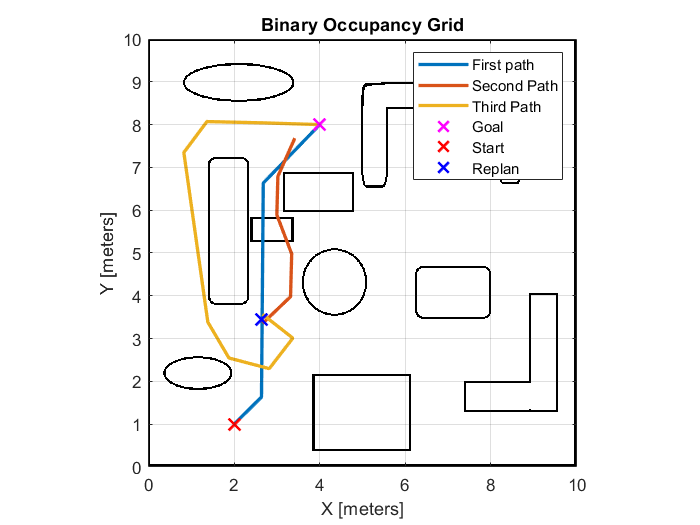

clf;
show(obstacleMap); grid on; hold on;
for i=2:length(pathStorage)
x = pathStorage(i).Path(:,1);
y = pathStorage(i).Path(:,2);
plotnr(i-1) = plot(x,y,'LineWidth',2);
end
goalPlot(1) = plot(goal(2),goal(1),'Marker','x','MarkerEdgeColor','magenta',...
 'LineWidth',1.5,'MarkerSize',10);
goalPlot(2) = plot(xio(1,20)+5,xio(1,19)+5,'Marker','x','MarkerEdgeColor','red',...
 'LineWidth',1.5,'MarkerSize',10);
goalPlot(3) = plot(2.65,3.44,'Marker','x','MarkerEdgeColor','blue',...
 'LineWidth',1.5,'MarkerSize',10);
set(goalPlot(1:3),'linestyle','none');
legend([plotnr(1:3),goalPlot(1:3)],{'First path','Second Path','Third Path','Goal','Start','Replan'});